x%%%%%% Projet : Classification d'Images pour la Reconnaissance d'Objets (CIFAR-10)
% Montassar Laboudi & Eya Sahli
%%%%%%% Partie évaluation de : AlexNet ---- Transfer Learning  
%%%%%%% DROP FACTOR 0.5 | EACH 3 EPOCHS 

%% 1. Téléchargement et Préparation des Données CIFAR-10
cifar10DataFolder = './cifar10Data';

if ~exist(cifar10DataFolder, 'dir')
    disp('Téléchargement des données CIFAR-10...');
    cifar10URL = 'https://www.cs.toronto.edu/~kriz/cifar-10-matlab.tar.gz';
    websave('cifar10Dataset.tar.gz', cifar10URL);
    untar('cifar10Dataset.tar.gz', cifar10DataFolder);
    disp('Téléchargement et extraction terminés.');
else
    disp('Données CIFAR-10 déjà disponibles.');
end

Données CIFAR-10 déjà disponibles.



% Charger les fichiers batch d'entraînement
trainImages = [];
trainLabels = [];
for batchIdx = 1:5
    batchFile = fullfile(cifar10DataFolder, 'cifar-10-batches-mat', sprintf('data_batch_%d.mat', batchIdx));
    batchData = load(batchFile);
    % Reshape des données : [3072 x N] -> [32 32 3 N]
    trainImages = cat(4, trainImages, reshape(batchData.data', [32, 32, 3, size(batchData.data, 1)]));
    trainLabels = [trainLabels; batchData.labels];
end

% Charger le batch de test
testBatchFile = fullfile(cifar10DataFolder, 'cifar-10-batches-mat', 'test_batch.mat');
testBatchData = load(testBatchFile);
testImages = reshape(testBatchData.data', [32, 32, 3, size(testBatchData.data, 1)]);
testLabels = testBatchData.labels;

% Correction des noms des classes
classNames = ["airplane", "automobile", "bird", "cat", "deer", "dog", "frog", "horse", "ship", "truck"];

% Conversion des labels en catégories
trainLabels = categorical(trainLabels, 0:9, classNames);
testLabels = categorical(testLabels, 0:9, classNames);

disp('Chargement des données CIFAR-10 terminé.');

Chargement des données CIFAR-10 terminé.



%% 2. Préparation des Données

% Définir la taille d'entrée pour AlexNet (227x227x3)
inputSize = [227, 227, 3];

% Redimensionnement des images d'entraînement
numTrainImages = size(trainImages, 4);
trainImagesResized = zeros([inputSize, numTrainImages], 'like', trainImages);
for i = 1:numTrainImages
    trainImagesResized(:,:,:,i) = imresize(trainImages(:,:,:,i), inputSize(1:2), 'bicubic');
end

% Redimensionnement des images de test
numTestImages = size(testImages, 4);
testImagesResized = zeros([inputSize, numTestImages], 'like', testImages);
for i = 1:numTestImages
    testImagesResized(:,:,:,i) = imresize(testImages(:,:,:,i), inputSize(1:2), 'bicubic');
end

% Création de l'augmentedImageDatastore pour le jeu de test
testData = augmentedImageDatastore(inputSize, testImagesResized);

% Séparation du jeu d'entraînement en ensembles entraînement et validation
rng(2001); % Pour la reproductibilité
idx = randperm(numTrainImages);
numVal = floor(0.2 * numTrainImages);
numTrainFinal = numTrainImages - numVal;

% Extraction pour l'entraînement
trainImagesFinal = trainImagesResized(:,:,:, idx(1:numTrainFinal));
trainLabelsFinal = trainLabels(idx(1:numTrainFinal));

% Extraction pour la validation
valImages = trainImagesResized(:,:,:, idx(numTrainFinal+1:end));
valLabels = trainLabels(idx(numTrainFinal+1:end));

% Création des datastores pour l'entraînement et la validation
trainData = augmentedImageDatastore(inputSize, trainImagesFinal, trainLabelsFinal);
valData   = augmentedImageDatastore(inputSize, valImages, valLabels);

disp('Préparation des données terminée.');

Préparation des données terminée.



%% 3. Chargement du Modèle AlexNet et Gel de 50% des Couches Apprenables

% Charger AlexNet pré-entraîné
net = alexnet;
lgraph = layerGraph(net);

% Remplacer la dernière fullyConnectedLayer et la classificationLayer pour CIFAR-10
% Dans AlexNet, la dernière fully connected s'appelle "fc8" et la couche de sortie "output"
newFcLayer = fullyConnectedLayer(10, 'Name', 'new_fc','WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10);
newOutputLayer = classificationLayer('Name', 'new_output');
lgraph = replaceLayer(lgraph, 'fc8', newFcLayer);
lgraph = replaceLayer(lgraph, 'output', newOutputLayer);

% Identification des indices des couches avec des paramètres apprenables
learnableLayerIndices = [];
for i = 1:numel(lgraph.Layers)
    layer = lgraph.Layers(i);
    if isprop(layer, 'WeightLearnRateFactor') || isprop(layer, 'BiasLearnRateFactor')
        learnableLayerIndices(end+1) = i;
    end
end

% Affichage du nombre de couches apprenables détectées
numLearnable = numel(learnableLayerIndices);
fprintf('Nombre de couches apprenables : %d\n', numLearnable);

Nombre de couches apprenables : 8



% Déterminer 50% de ces couches pour le gel
numFreeze = floor(numLearnable / 2);
fprintf('Gel de %d couches sur %d (soit environ 50%% des couches apprenables)\n', numFreeze, numLearnable);

Gel de 4 couches sur 8 (soit environ 50% des couches apprenables)



% Gel des premières 50% des couches apprenables
for k = 1:numFreeze
    idxLayer = learnableLayerIndices(k);
    layer = lgraph.Layers(idxLayer);
    
    % Geler les paramètres d'apprentissage
    if isprop(layer, 'WeightLearnRateFactor')
        layer.WeightLearnRateFactor = 0;
    end
    if isprop(layer, 'BiasLearnRateFactor')
        layer.BiasLearnRateFactor = 0;
    end
    
    % Pour les couches de Batch Normalization (si présentes)
    if isa(layer, 'nnet.cnn.layer.BatchNormalizationLayer')
        layer.ScaleLearnRateFactor = 0;
        layer.OffsetLearnRateFactor = 0;
    end
    
    % Mise à jour de la couche dans le layerGraph
    lgraph = replaceLayer(lgraph, layer.Name, layer);
end

% Visualiser l'architecture modifiée
analyzeNetwork(lgraph);

%% 4. Entraînement du Modèle
options = trainingOptions('adam', ...
    'MaxEpochs', 30, ... 
    'MiniBatchSize', 128, ...
    'InitialLearnRate', 0.001, ... 
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.5, ...  % Facteur de réduction du taux d'apprentissage
    'LearnRateDropPeriod', 3, ...     % Réduction toutes les 3 epochs
    'Shuffle', 'every-epoch', ...
    'ValidationData', valData, ...
    'ValidationFrequency', 312, ... 
    'Verbose', true, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'gpu', ...
    'ValidationPatience', 2);

disp('Entraînement du modèle en cours...');

Entraînement du modèle en cours...


alexNetTrained = trainNetwork(trainData, lgraph, options);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:38 |        8.59% |       16.50% |       5.0182 |       9.7620 |          0.0010 |
|       1 |          50 |       00:00:58 |       64.06% |              |       1.3594 |              |          0.0010 |
|       1 |         100 |       00:01:18 |       63.28% |              |       1.0525 |              |          0.0010 |
|       1 |         150 |       00:01:38 |       64.06% |              |       1.0625 |              |          0.

disp('Entraînement terminé.');

Entraînement terminé.



%% 5. Évaluation des Performances du Modèle AlexNet

% Classification sur le jeu de test
[YPred, scores] = classify(alexNetTrained, testData);

% Calcul de l'accuracy en comparant avec testLabels
accuracy = mean(YPred == testLabels);
disp(['Accuracy du modèle : ', num2str(accuracy * 100), '%']);

Accuracy du modèle : 80.07%



% Calcul de la matrice de confusion
confMatrixRaw = confusionmat(testLabels, YPred);

% Calcul des vrais positifs (TP), faux positifs (FP) et faux négatifs (FN) par classe
TP = diag(confMatrixRaw);
FP = sum(confMatrixRaw, 1)' - TP;  % Somme de chaque colonne moins TP
FN = sum(confMatrixRaw, 2) - TP;     % Somme de chaque ligne moins TP

% Calcul des métriques par classe (avec protection contre la division par zéro)
precisionClass = TP ./ (TP + FP + eps);
recallClass    = TP ./ (TP + FN + eps);
f1Class        = 2 * (precisionClass .* recallClass) ./ (precisionClass + recallClass + eps);

% Affichage des métriques par classe
disp('Métriques par classe :');

Métriques par classe :


for i = 1:length(classNames)
    fprintf('Classe %s : Précision = %.2f%% | Rappel = %.2f%% | F1-score = %.2f%%\n', ...
        classNames(i), precisionClass(i)*100, recallClass(i)*100, f1Class(i)*100);
end

Classe airplane : Précision = 77.22% | Rappel = 87.80% | F1-score = 82.17%
Classe automobile : Précision = 88.78% | Rappel = 91.00% | F1-score = 89.88%
Classe bird : Précision = 76.16% | Rappel = 73.80% | F1-score = 74.96%
Classe cat : Précision = 55.90% | Rappel = 64.90% | F1-score = 60.06%
Classe deer : Précision = 86.55% | Rappel = 72.70% | F1-score = 79.02%
Classe dog : Précision = 69.47% | Rappel = 78.50% | F1-score = 73.71%
Classe frog : Précision = 88.62% | Rappel = 83.30% | F1-score = 85.88%
Classe horse : Précision = 85.38% | Rappel = 81.20% | F1-score = 83.24%
Classe ship : Précision = 92.25% | Rappel = 82.10% | F1-score = 86.88%
Classe truck : Précision = 89.24% | Rappel = 85.40% | F1-score = 87.28%



% Calcul des métriques globales (micro-moyenne)
globalPrecision = sum(TP) / (sum(TP) + sum(FP) + eps);
globalRecall    = sum(TP) / (sum(TP) + sum(FN) + eps);
globalF1Score   = 2 * (globalPrecision * globalRecall) / (globalPrecision + globalRecall + eps);

% Taux d'erreur global
errorRate = 1 - accuracy;

% Affichage des métriques globales
disp(' ');

disp('Évaluation globale de l''architecture :');

Évaluation globale de l'architecture :


fprintf('Accuracy           : %.2f%%\n', accuracy * 100);

Accuracy           : 80.07%


fprintf('Précision globale  : %.2f%%\n', globalPrecision * 100);

Précision globale  : 80.07%


fprintf('Rappel global      : %.2f%%\n', globalRecall * 100);

Rappel global      : 80.07%


fprintf('F1-score global    : %.2f%%\n', globalF1Score * 100);

F1-score global    : 80.07%


fprintf('Taux d''erreur     : %.2f%%\n', errorRate * 100);

Taux d'erreur     : 19.93%


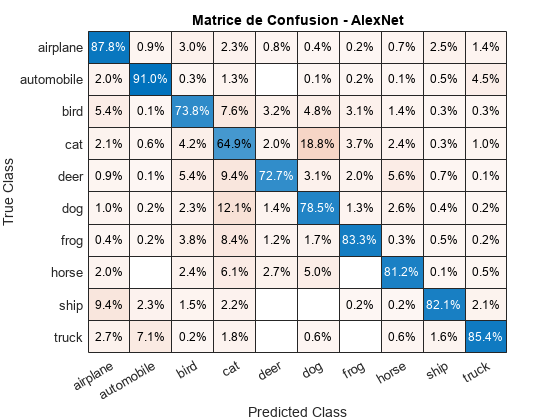


% Affichage de la matrice de confusion normalisée par ligne
figure;
confusionchart(testLabels, YPred, 'Normalization','row-normalized');
title('Matrice de Confusion - AlexNet');

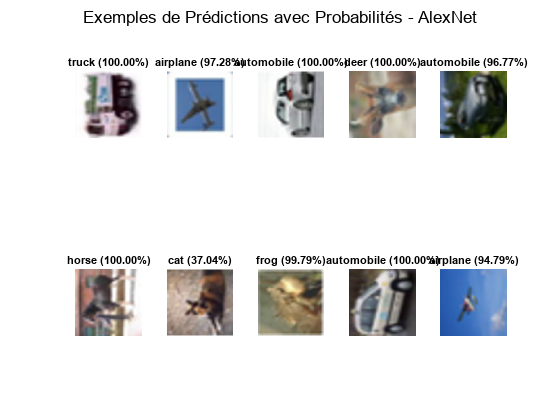


%% 6. Affichage des Prédictions
figure;
numImagesToShow = 10; % Nombre d'exemples à afficher
indices = randperm(numTestImages, numImagesToShow);

for i = 1:numImagesToShow
    subplot(2, 5, i);
    img = testImagesResized(:,:,:, indices(i));
    imshow(uint8(img));
    
    % Afficher le label prédit et les probabilités associées
    label = YPred(indices(i));
    prob = scores(indices(i), :);
    
    % Titre avec le label prédit et la probabilité maximale
    [maxProb, maxIdx] = max(prob);
    title(sprintf('%s (%.2f%%)', classNames(maxIdx), maxProb * 100));
end
sgtitle('Exemples de Prédictions avec Probabilités - AlexNet');